# Convert librosa Audio Feature Extraction To MATLAB

## This Example Shows How to:

- Convert librosa Python feature extraction code to MATLAB.

- Using the MATLAB feature extraction code, translate a Python speech command recognition system to a MATLAB system where Python is not required.

## Overview

Audio and speech AI systems often include feature extraction. Importing AI audio models trained in non-MATLAB frameworks into MATLAB usually consists of two steps:

- Import the pretrained network to MATLAB.

- Translate the feature extraction performed in the non-MATLAB framework to MATLAB code.

This example focuses on the second step of this process. In particular, you learn how to translate librosa feature extraction functions to their MATLAB equivalents. 

The example covers three of the most popular audio feature extraction algorithms:

- Short-time Fourier transform (STFT) and its inverse (ISTFT).

- Mel spectrogram.

- Mel-frequency cepstral coefficients (MFCC).

You also leverage the converted feature extraction code to translate a Python deep learning speech command recognition system to MATLAB. The Python system uses PyTorch for the pretrained network, and librosa for mel spectrogram feature extraction.

## Requirements

- [MATLAB®](https://www.mathworks.com/) R2021b or later

- [Audio Toolbox™](https://www.mathworks.com/products/audio.html)

- [Deep Learning Toolbox™](https://www.mathworks.com/products/deep-learning.html)

The Python code uses the following packages:

- librosa version 0.9.2

- PyTorch version 1.10.2

## Mapping librosa Code to MATLAB Code

### STFT and ISTFT

#### Execute librosa Code

You start with translating STFT and ISTFT librosa code to MATLAB. 

The Python script [`librosaSTFT.py`](matlab:open('./PythonCode\librosastft.py')) uses the librosa functions `stft` and `istft`.

Inspect the contents of the script.

addpath("PythonCode\")
pythonScript = fullfile(pwd,"PythonCode","librosastft.py");
type(pythonScript)

import librosa

import warnings
warnings.filterwarnings("ignore")

# Read audio
sr = 16e3
samples, sr = librosa.load(filename, sr)

# STFT
stftOut = librosa.stft(samples, n_fft=512, hop_length=160,
                       win_length=512,window="hann",
                       center=True)

# ISTFT
istftOut = librosa.istft(stftOut, n_fft=512, hop_length=160,
                         win_length=512,window="hann", center=True)


You can execute Python scripts and commands from MATLAB. For more information about this functionality, see [Call Python from MATLAB](https://www.mathworks.com/help/matlab/call-python-libraries.html) in the documentation. In this example, you use [pyrunfile](https://www.mathworks.com/help/matlab/ref/pyrunfile.html) to run a Python script in MATLAB. 

Use pyrunfile to call the Python script. Pass the name of the test audio file as an input argument. Return variables computed in the Python script to MATLAB by specifying them as output arguments.

filename = fullfile(pwd,"samples","yes.flac");
[stftOut1, istftOut1] = pyrunfile(pythonScript,["stftOut","istftOut"],filename=filename);
stftOut1 = single(stftOut1);
istftOut1 = single(istftOut1);

#### Implement Equivalent MATLAB Code

To perform the equivalent STFT and ISTFT computations in MATLAB, you use the MATLAB functions [librosa.stft](matlab:open('./HelperFiles\+librosa\stft.m')) and [librosa.istft](matlab:open('./HelperFiles\+librosa\istft.m')). The name-value arguments of these functions match the name-value arguments of their librosa counterparts.

Load the sample audio signal in MATLAB.

addpath(fullfile(pwd,"HelperFiles"))
[samples,fs] = audioread(filename);
samples = single(samples);

Now compute the STFT. Use the same name-value arguments as in the Python script.

stftOut2 = librosa.stft(samples,FFTLength=512,HopLength=160,...
                       WindowLength=512,Window="hann",...
                       Center=true);

Compare the Python and MATLAB STFT values by computing the error.

fprintf("STFT error: %f\n", norm(stftOut1(:)-stftOut2(:)));

STFT error: 0.000003


Note that calling librosa.stft with no output arguments plots the magnitude of the STFT.

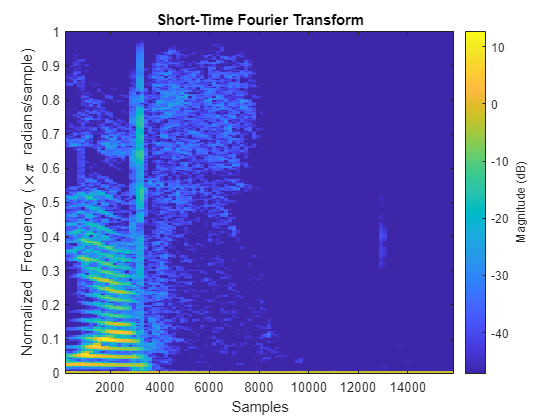

figure;
librosa.stft(samples,FFTLength=512,HopLength=160,...
                       WindowLength=512,Window="hann",...
                       Center=false);

Now compute the ISTFT in MATLAB by using the same name-value arguments as the Python script.

istftOut2 = librosa.istft(stftOut2,FFTLength=512,HopLength=160,...
                       WindowLength=512,Window="hann",...
                       Center=true);

Compare the MATLAB and librosa ISTFT values.

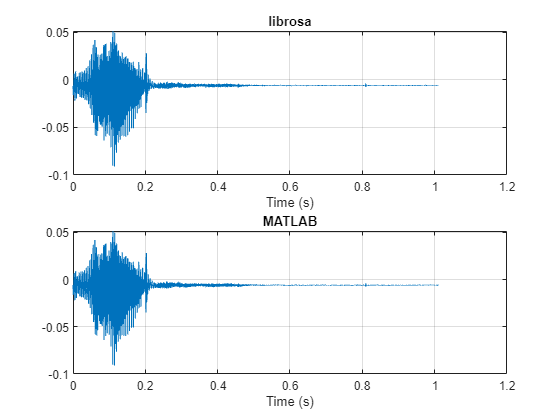

figure
subplot(2,1,1)
L = length(istftOut1);
t = (0:L-1)/fs;
plot(t,istftOut1)
grid on 
xlabel("Time (s)")
title("librosa")
subplot(2,1,2)
t = (0:L-1)/fs;
plot(t,istftOut2)
grid on 
xlabel("Time (s)")
title("MATLAB")

Compute the error.

fprintf("ISTFT error: %f\n", norm(istftOut1(:)-istftOut2(:))); 

ISTFT error: 0.001271


#### Generate MATLAB Code from librosa.stft and librosa.istft

To generate MATLAB code that implements librosa's STFT with documented MATLAB function, specify `GenerateMATLABCode=true `in the call to `librosa.stft. `In this case, the generated MATLAB code uses the function [stft](https://www.mathworks.com/help/signal/ref/stft.html).

out = librosa.stft(samples,FFTLength=512,HopLength=160,...
                       WindowLength=512,Window="hann",...
                       Center=true,GenerateMATLABCode=true);

### Mel Filter Bank

Next, you map librosa's mel filter bank function to MATLAB. Mel filter banks are integral to mel spectrograms and MFCC computations.

Inspect the Python script that builds the filter bank.

pythonScript = fullfile(pwd,"PythonCode","librosamel.py");
type(pythonScript)

import librosa

import warnings
warnings.filterwarnings("ignore")

sr = 16e3

# Mel Filter bank
melOut = librosa.filters.mel(sr=sr,n_fft=512, n_mels=50,
                             norm="slaney", htk=True)


Execute the script.

melOut1 = pyrunfile(pythonScript,"melOut");
melOut1 = single(melOut1);

Use [librosa.mel](matlab:open('./HelperFiles\+librosa\mel.m')) to construct the same filter bank in MATLAB.

melOut2 = librosa.mel(SampleRate=fs,FFTLength=512,NumBands=50,...
                       Normalization="Slaney",HTK=true);

Plot and compare the librosa and MATLAB filter banks.

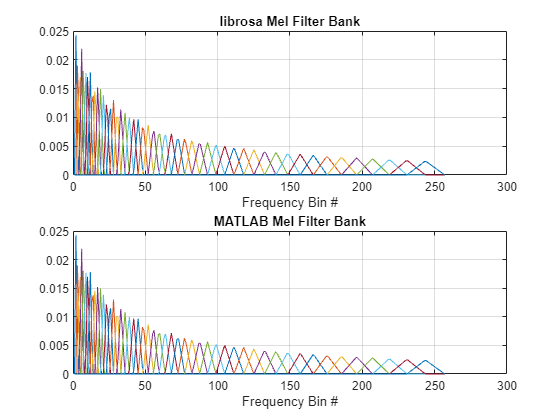

Fc = mel2hz(linspace(0,fs/2,50));
figure;
subplot(2,1,1)
plot(melOut1.')
grid on
title("librosa Mel Filter Bank")
xlabel("Frequency Bin #")
subplot(2,1,2)
plot(melOut2.')
grid on
title("MATLAB Mel Filter Bank")
xlabel("Frequency Bin #")

Compute the error.

fprintf("Mel filter bank error: %f\n", norm(melOut1(:)-melOut2(:)))

Mel filter bank error: 0.000000


Similar to `librosa.stft` and` librosa.istft`, specify `GenerateMATLABCode=true `to generate MATLAB code that uses documented functions. In this case, the generated code uses [designAuditoryFilterBank](https://www.mathworks.com/help/audio/ref/designauditoryfilterbank.html).

librosa.mel(SampleRate=fs,FFTLength=512,NumBands=50,...
                       Normalization="Slaney",HTK=true,...
                       GenerateMATLABCode=true);

### Mel Spectrogram

Next, you map librosa's mel spectrogram function to MATLAB. 

Inspect the Python script that computes the mel spectrogram.

pythonScript = fullfile(pwd,"PythonCode","librosamelspectrogram.py");
type(pythonScript)

import librosa

import warnings
warnings.filterwarnings("ignore")

# Read audio
sr = 16e3
samples, sr = librosa.load(filename, sr)

# Mel spectrogram
melSpectrogramOut = librosa.feature.melspectrogram(samples,sr=sr,
                    n_fft=512,n_mels=50, norm="slaney",htk=True,hop_length=160,
                    win_length=512,window="hann",center=False,power=2)


Execute the script.

melSpectrogramOut1 = pyrunfile(pythonScript,"melSpectrogramOut",filename=filename);
melSpectrogramOut1 = single(melSpectrogramOut1);

Use [librosa.melSpectrogram](matlab:open('./HelperFiles\+librosa\melSpectrogram.m')) to compute the same mel spectrogram in MATLAB.

melSpectrogramOut2 = librosa.melSpectrogram(samples,SampleRate=fs,FFTLength=512,NumBands=50,...
                       Center=false,HopLength=160,WindowLength=512,Window="hann",...
                       Normalization="Slaney", HTK=true, Power=2);

Compute the error.

fprintf("Mel spectrogram error: %f\n", norm(melSpectrogramOut1(:)-melSpectrogramOut2(:)))

Mel spectrogram error: 0.000000


Similar to other functions, specify `GenerateMATLABCode=true `to generate MATLAB code that uses documented MATLAB functions. In this case, the generated code uses [stft](https://www.mathworks.com/help/signal/ref/stft.html) and [designAuditoryFilterBank](https://www.mathworks.com/help/audio/ref/designauditoryfilterbank.html).

librosa.melSpectrogram(samples,SampleRate=fs,FFTLength=512,NumBands=50,...
                       Center=false,HopLength=160,WindowLength=512,Window="hann",...
                       Normalization="Slaney", HTK=true, Power=2,...
                       GenerateMATLABCode=true);

### MFCC

Finally, you map librosa's MFCC computation function to MATLAB.

Inspect the Python script that computes MFCC.

pythonScript = fullfile(pwd,"PythonCode","librosamfcc.py");
type(pythonScript)

import librosa

import warnings
warnings.filterwarnings("ignore")

# Read audio
sr = 16e3
samples, sr = librosa.load(filename, sr)

# MFCC
mfccOut = librosa.feature.mfcc(samples,sr=sr,n_fft=512, n_mels=50,
                               hop_length=160,win_length=512,
                               window="hann", htk=True,power=2,
                               dct_type=2,lifter=.2)


Execute the script.

mfccOut1 = pyrunfile(pythonScript,"mfccOut",filename=filename);
mfccOut1 = single(mfccOut1);

Use [librosa.mfcc](matlab:open('./HelperFiles\+librosa\mfcc.m')) to compute the same MFCC in MATLAB.

mfccOut2 = librosa.mfcc(samples,SampleRate=fs,FFTLength=512,NumBands=50,FMin=10,...
                       HopLength=160,WindowLength=512,Window="hann",...
                       HTK=true,Power=2,DCTType=2,Lifter=0.2);

Compute the error.

fprintf("MFCC error: %f\n", norm(mfccOut1(:)-mfccOut2(:)))

MFCC error: 0.000981


Similar to other functions, specify `GenerateMATLABCode=true `to generate MATLAB code that uses documented functions. In this case, the generated code uses [stft](https://www.mathworks.com/help/signal/ref/stft.html), [dct](https://www.mathworks.com/help/signal/ref/dct.html), and [designAuditoryFilterBank](https://www.mathworks.com/help/audio/ref/designauditoryfilterbank.html).

 librosa.mfcc(samples,SampleRate=fs,FFTLength=512,NumBands=50,FMin=10,...
                       HopLength=160,WindowLength=512,Window="hann",...
                       HTK=true,Power=2,DCTType=2,Lifter=0.2,...
                       GenerateMATLABCode=true);

## Import Python Speech Command System to MATLAB

You now use the feature extraction mapping functionality to translate a Python pretrained speech recognition system to MATLAB.

### System Description 

The deep learning speech command recognition system was trained in Python.

The system recognizes the following commands:

- "yes"

- "no"

- "up"

- "down"

- "left"

- "right"

- "on"

- "off"

- "stop"

- "go"

The system is comprised of a convolutional neural network. The network accepts mel spectrograms as an input. 

For the training workflow, a supervized learning approach is followed, where mel spectrograms labeled with commands are fed to the network.

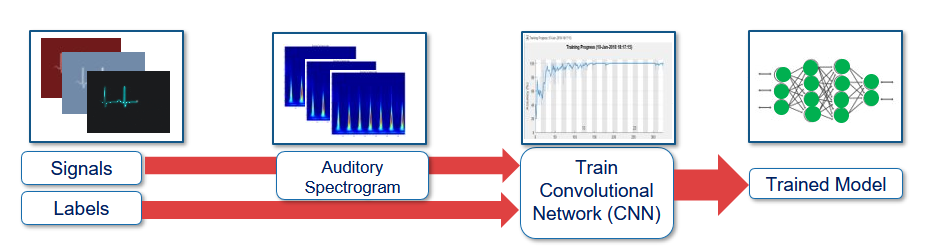

The following were used to train the command recognition system:

- **PyTorch** to design and train the model.

- librosa to perform feature extraction (auditory spectrogram computation).

You perform speech recognition in Python by first extracting an mel spectrogram from an audio signal, and then feeding the spectrogram to the trained convolutional network.

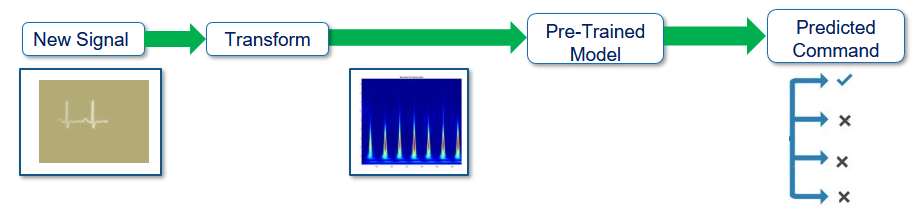

### Perform Speech Command Recognition in Python

The Python script [`InferSpeechCommands.py`](matlab:open('./PythonCode\InferSpeechCommands.py')) performs speech command recognition. 

Execute Python inference in MATLAB. The Python script prints out the recognized keyword. Return the network activations.

cd("PythonCode")
pythonScript = "InferSpeechCommands.py";
[pytorchActivations,mm] = pyrunfile(pythonScript,["activations","z"],filename=filename);

Recognized command: yes


cd ..

### Convert the Pretrained Network to MATLAB

You first import the PyTorch pretrained network to MATLAB using MATLAB's [model import-export functionality](https://www.mathworks.com/help/deeplearning/deep-learning-import-and-export.html?s_tid=CRUX_lftnav). In this example, you use [importONNXNetwork](https://www.mathworks.com/help/deeplearning/ref/importonnxnetwork.html). The function imports a version of the network that was saved to the  Open Neural Network Exchange (ONNX) format. To see how the PyTorch model can be saved to an ONNX format, refer to [convertModelToONNX.py](matlab:open('./PythonCode\convertModelToONNX.py')).

onnxFile = "cmdRecognitionPyTorch.onnx";

Import the network to MATLAB

net = importONNXNetwork(onnxFile)

net =   DAGNetwork with properties:

         Layers: [19×1 nnet.cnn.layer.Layer]
    Connections: [18×2 table]
     InputNames: {'input'}
    OutputNames: {'RegressionLayer_output'}


### Perform Speech Command Recognition in MATLAB

Use` librosa.melSpectrogram `to perform feature extraction. Call the function with the same name-value arguments as the Python inference.

spect = librosa.melSpectrogram(samples,SampleRate=fs, FFTLength=512,NumBands=50,...
                       Center=false,HopLength=160,WindowLength=512,Window="hann",...
                       Normalization="Slaney", HTK=true, Power=2);
spect = log10(spect + 1e-6);
MATLABActivations = predict(net,spect.');

Compare MATLAB and PyTorch activations.

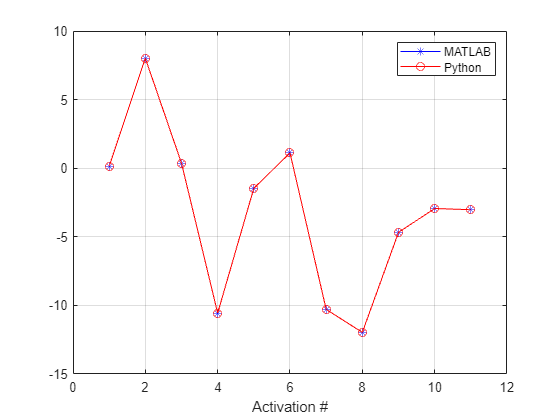

figure
plot(MATLABActivations,"b*-")
hold on
grid on
plot(pytorchActivations,"ro-")
xlabel("Activation #")
legend("MATLAB", "Python")

Verify the spoken command in MATLAB.

CLASSES = ["unknown" " yes" " no" " up" " down" " left" " right" " on" " off" " stop" "go"];
[~,ind] = max(MATLABActivations);
fprintf("Recognized command: %s\n",CLASSES(ind))

Recognized command:  yes


*Copyright 2022 The MathWorks, Inc.*